# Earth to Mars:

Circle to Circle case:

r1 = 1 AU;

r2 = 1.524 AU;

Canonical units:

1 AU = 1.495978e8 km

2 $\pi$ TU = 1 year

$\mu$=1 AU^3/TU

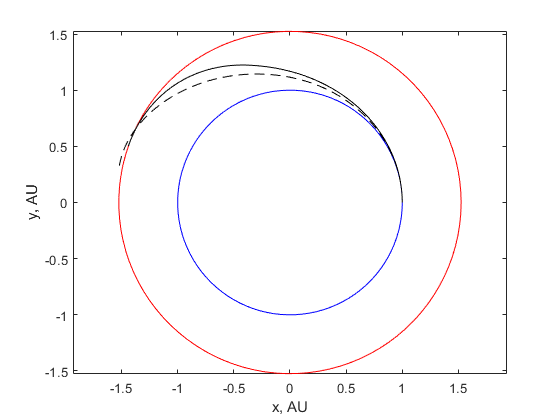

clc
close all
%% Minimize time from Earth to Mars
% initial circular orbit in AU, TU
% States: r, theta, vr, vt, Ta
c = 0.988; % AU/TU, effective exhaust velocity, Isp = 3000 sec
Tao = 0.1; % AU/TU^2, initial thrust acceleration
so = [1, 0, 0, 1, Tao];
% integrate state equations forward using alpha in the direction of the
% velocity vector
[XT, XS] = ode45(@(t,s)eomxguess(t,s,c),linspace(0,4,101),so);
% integrate the lambda equations backwards
Lo = [-5,5,-5,1];
[~, LS] = ode45(@(t,s)eomLguess(t,s,c,XT,XS),XT(end:-1:1),Lo);
LS = LS(end:-1:1,:); % reverse order of lambdas
% plot guess
theta = linspace(0,2*pi);
plot(cos(theta),sin(theta),'-b',1.524*cos(theta),1.524*sin(theta),'-r',...
    XS(:,1).*cos(XS(:,2)),XS(:,1).*sin(XS(:,2)),'--k')
xlabel('x, AU')
ylabel('y, AU')
axis equal
%
% setup bvp4c
% SOL = BVP4C(ODEFUN,BCFUN,SOLINIT)
% ODEFUN(X,Y) must return a column vector representing
%    f(x,y). For column vectors YA and YB, BCFUN(YA,YB) must return a column 
%    vector representing bc(y(a),y(b)).  SOLINIT is a structure with fields  
%        x -- ordered nodes of the initial mesh with 
%             SOLINIT.x(1) = a, SOLINIT.x(end) = b
%        y -- initial guess for the solution with SOLINIT.y(:,i)
%             a guess for y(x(i)), the solution at the node SOLINIT.x(i)
solinit.x = XT/XT(end); % tau, 0 to 1
solinit.y = [XS, LS]';
solinit.parameters = XT(end); % tf
options = bvpset('RelTol',1e-6,'AbsTol',1e-9);
sol = bvp4c(@(t,s,tf)ELeom(t,s,tf,1),@bcfunc,solinit,options);
hold on
plot(sol.y(1,:).*cos(sol.y(2,:)),sol.y(1,:).*sin(sol.y(2,:)),'-k')

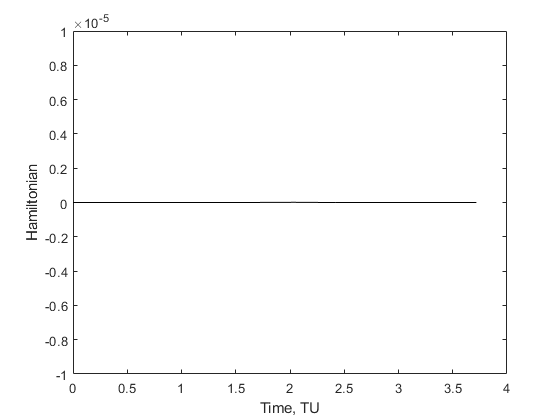

alpha = atan2(-sol.y(7,:),-sol.y(8,:));
H = 1+sol.y(6,:).*sol.y(3,:)+...
    sol.y(7,:).*(-1./(sol.y(1,:).^2)+(sol.y(4,:).^2)./sol.y(1,:)+sol.y(5,:).*sin(alpha))+...
    sol.y(8,:).*(-sol.y(3,:).*sol.y(4,:)./sol.y(1,:)+sol.y(5,:).*cos(alpha))+...
    sol.y(9,:).*(sol.y(5,:).^2)/0.988;
figure
plot(sol.x*sol.parameters,H,'-k')
xlabel('Time, TU')
ylabel('Hamiltonian')
ylim([-1e-5,1e-5])

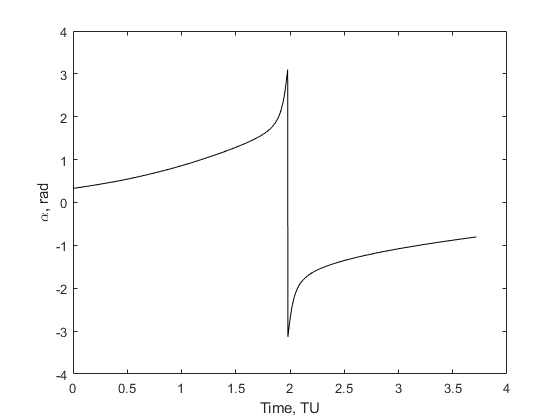

figure
plot(sol.x*sol.parameters,atan2(-sol.y(7,:),-sol.y(8,:)),'-k')
xlabel('Time, TU')
ylabel('\alpha, rad')

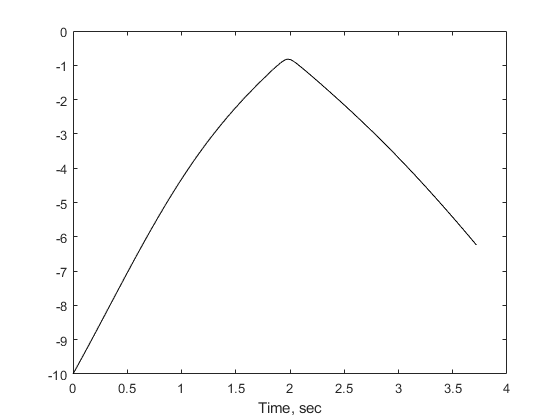

figure
plot(sol.x*sol.parameters,-sqrt(sol.y(7,:).^2+sol.y(8,:).^2)+sol.y(9,:).*sol.y(5,:)/c,'-k')
xlabel('Time, sec')

## Fixed Time (tf>tmin), same Ta

Generate guess based on min time solution

Assumes a Thrust-Coast-Thrust solution

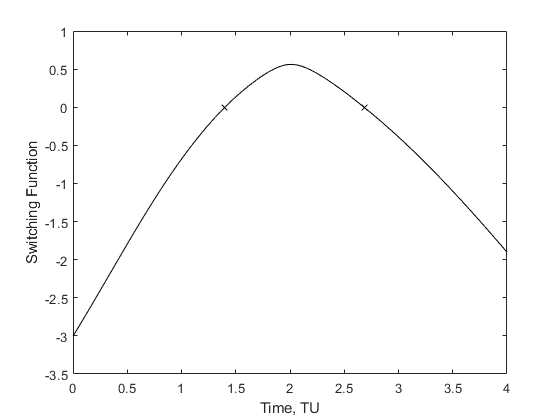

T = sol.x*4;
S = sol.y';
tf = 4; % TU
t1 = 1.84; % TU
t2 = 2.12; % TU
solinit.x = linspace(0,1,21);
% First arc: 0 to t1, Thrust
y1 = interp1(T,S,linspace(0,t1,21))';
% Second arc: t1 to t2, Coast
y2 = interp1(T,S,linspace(t1,t2,21))';
% Third arc: t2 to tf, Thrust
y3 = interp1(T,S,linspace(t2,tf,21))';
solinit.y = [y1;y2;y3];
solinit.parameters = [t1,t2]; % switching times
sol2 = bvp4c(@(t,s,times)ELeom3(t,s,times,tf),@bcfunc3,solinit,options);
figure
time = [sol2.x.*sol2.parameters(1),...
        sol2.x.*(sol2.parameters(2)-sol2.parameters(1))+sol2.parameters(1),...
        sol2.x.*(tf-sol2.parameters(2))+sol2.parameters(2)];
r = [sol2.y(1,:),sol2.y(10,:),sol2.y(19,:)];
theta = [sol2.y(2,:),sol2.y(11,:),sol2.y(20,:)];
vr = [sol2.y(3,:),sol2.y(12,:),sol2.y(21,:)];
vt = [sol2.y(4,:),sol2.y(13,:),sol2.y(22,:)];
Ta = [sol2.y(5,:),sol2.y(14,:),sol2.y(23,:)];
Lr = [sol2.y(6,:),sol2.y(15,:),sol2.y(24,:)];
Lvr = [sol2.y(7,:),sol2.y(16,:),sol2.y(25,:)];
Lvt = [sol2.y(8,:),sol2.y(17,:),sol2.y(26,:)];
LTa = [sol2.y(9,:),sol2.y(18,:),sol2.y(27,:)];
switchingfunc = 1-sqrt(Lvr.^2+Lvt.^2)+LTa.*Ta/c;
plot(time,switchingfunc,'-k',sol2.parameters,[0,0],'xk')
xlabel('Time, TU')
ylabel('Switching Function')

fprintf('Spacecraft thrusts for %4.3f TU of the 4 TU trajectory; less than the minimum time of %4.3f TU \n',...
    [sol2.parameters(1)+tf-sol2.parameters(2),sol.parameters(1)])

Spacecraft thrusts for 2.717 TU of the 4 TU trajectory; less than the minimum time of 3.718 TU 


fprintf('Delta-v = %4.3f AU/TU \n',c*log(sol2.y(5,end)/sol2.y(5,1)))

Delta-v = 0.151 AU/TU 


fprintf('Min Time Delta-v = %4.3f AU/TU \n',c*log(sol.y(5,end)/sol.y(5,1)))

Min Time Delta-v = 0.466 AU/TU 


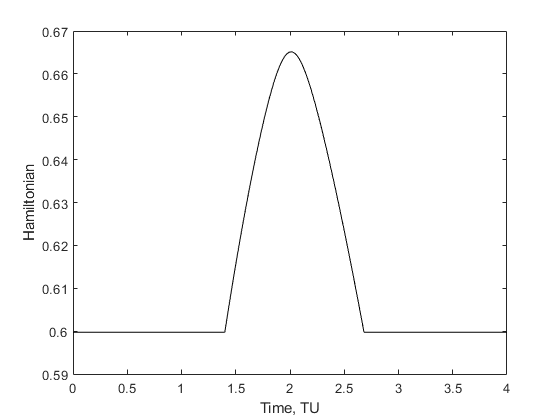

alpha = atan2(-Lvr,-Lvt);
throttle = switchingfunc<1;
H = throttle+Lr.*vr+...
    Lvr.*(-1./(r.^2)+(vt.^2)./r+Ta.*sin(alpha))+...
    Lvt.*(-vr.*vt./r+Ta.*cos(alpha))+...
    LTa.*(Ta.^2)/0.988;
figure
plot(time,H,'-k')
xlabel('Time, TU')
ylabel('Hamiltonian')

Discontinuity during coasting arc due to no control being used since thrust is off. Best to only have 1st and 3rd arcs when throttle is on but more complicated to code the starting conditions of the 3rd arc based on the terminal conditions of the 1st arc. Good Space Mechanics problem but too much for Optimization class.

function ds = eomxguess(t,s,c)
ds = zeros(5,1);
if t<1.8
    alpha = atan2(s(3),s(4)); % velocity direction
else
    alpha = atan2(-s(3),-s(4)); % against velocity direction
end
ds(1) = s(3);
ds(2) = s(4)/s(1);
ds(3) = -1/(s(1)^2)+(s(4)^2)/s(1)+s(5)*sin(alpha);
ds(4) = -s(3)*s(4)/s(1)+s(5)*cos(alpha);
ds(5) = (s(5)^2)/c;
end

function ds = eomLguess(t,s,c,XT,XS)
% s(1) = Lambda_r, s(2) = Lambda_Vr, s(3) = Lambda_Vt, s(4) = Lambda_Ta
ds = zeros(4,1);
XSt = interp1(XT,XS,t);
if t<1.8
    alpha = atan2(XSt(3),XSt(4)); % velocity direction
else
    alpha = atan2(-XSt(3),-XSt(4)); % against velocity direction
end
ds(1) = (1/(XSt(1)^2))*(s(2)*(XSt(4)^2-2/XSt(1))-s(3)*XSt(3)*XSt(4));
ds(2) = -s(1)+s(3)*XSt(4)/XSt(1);
ds(3) = (1/XSt(1))*(s(3)*XSt(3)-s(2)*2*XSt(4));
ds(4) = -(s(2)*sin(alpha)+s(3)*cos(alpha)+2*s(4)*XSt(5)/c);
end

function con = bcfunc(sa,sb,~)
con(1) = sa(1)-1; % initial r
con(2) = sa(2); % initial theta
con(3) = sa(3); % initial vr
con(4) = sa(4)-1; % initial vt
con(5) = sa(5)-0.1; % initial Ta
con(6) = sb(1)-1.524; % rf constraint
con(7) = sb(3); % vrf constraint
con(8) = sb(4)-1/sqrt(1.524); % vtf constraint
con(9) = sb(9)-1; % lambda Taf constraint
alpha = atan2(-sb(7),-sb(8));
H = 1+sb(6:9)'*[sb(3);
     -1/(sb(1)^2)+(sb(4)^2)/sb(1)+sb(5)*sin(alpha);
     -sb(3)*sb(4)/sb(1)+sb(5)*cos(alpha);
     (sb(5)^2)/0.988];
con(10) = H; % transversality condition, H(tf) = 0
end

function ds = ELeom(~,s,tfinal,throttle)
ds = zeros(9,1);
alpha = atan2(-s(7),-s(8));
ds(1) = s(3);
ds(2) = s(4)/s(1);
ds(3) = -1/(s(1)^2)+(s(4)^2)/s(1)+throttle*s(5)*sin(alpha);
ds(4) = -s(3)*s(4)/s(1)+throttle*s(5)*cos(alpha);
ds(5) = throttle*(s(5)^2)/0.988;
ds(6) = (1/(s(1)^2))*(s(7)*(s(4)^2-2/s(1))-s(8)*s(3)*s(4));
ds(7) = -s(6)+s(8)*s(4)/s(1);
ds(8) = (1/s(1))*(s(8)*s(3)-s(7)*2*s(4));
ds(9) = -(s(7)*sin(alpha)+s(8)*cos(alpha)+throttle*2*s(9)*s(5)/0.988);
ds = ds*tfinal; % wrt to tau
end


function ds = ELeom3(~,s,tvec,tf)
% s(1:9) arc 1
% s(10:18) arc 2
% s(19:27) arc 3
% tvec = [t1,t2,tf]
ds(1:9)   = ELeom(0,s(1:9),tvec(1),1);
ds(10:18) = ELeom(0,s(10:18),tvec(2)-tvec(1),0);
ds(19:27) = ELeom(0,s(19:27),tf-tvec(2),1);
end


function con = bcfunc3(po,pf,~)
% initial time, initial states
con(1) = po(1) - 1; 
con(2) = po(2);
con(3) = po(3);
con(4) = po(4) - 1;
con(5) = po(5) - 0.1;
% time t1
con(6:14) = pf(1:9) - po(10:18); % continuity
con(15) = 1-sqrt(pf(7)^2+pf(8)^2)+pf(9)*pf(5)/0.988; % switching func = 0
% time t2
con(16:24) = pf(10:18) - po(19:27); % continuity
con(25) = 1-sqrt(pf(16)^2+pf(17)^2)+pf(18)*pf(14)/0.988; % switching func = 0
% final time
con(26) = pf(19) - 1.524;
con(27) = pf(21);
con(28) = pf(22) - 1/sqrt(1.524);
con(29) = pf(27) - 1;
end





